# Lab 9 by Cole Bardin 		Section 61

## Matrix Laplace Method and Linear Systems

## Part A: The Harmonic Oscillator

clc, clear, close all
syms s;
A = [0, 1; -1, 0]; x0 = [3;4];
% a
Rs = inv(s*eye(2)-A)

$$Rs = \left(\begin{array}{cc} \frac{s}{s^{2}+1} & \frac{1}{s^{2}+1}\\ -\frac{1}{s^{2}+1} & \frac{s}{s^{2}+1} \end{array}\right)$$

% b
Ts = ilaplace(Rs)

$$Ts = \left(\begin{array}{cc} \cos\left(t\right) & \sin\left(t\right)\\ -\sin\left(t\right) & \cos\left(t\right) \end{array}\right)$$

% c
x = Ts*x0

$$x = \left(\begin{array}{c} 3\,\cos\left(t\right)+4\,\sin\left(t\right)\\ 4\,\cos\left(t\right)-3\,\sin\left(t\right) \end{array}\right)$$


% d. Plot the solution x2 (vertical axis) versus x1
x1 = matlabFunction(x(1))

x1 = function_handle with value:
    @(t)cos(t).*3.0+sin(t).*4.0


x2 = matlabFunction(x(2))

x2 = function_handle with value:
    @(t)cos(t).*4.0-sin(t).*3.0


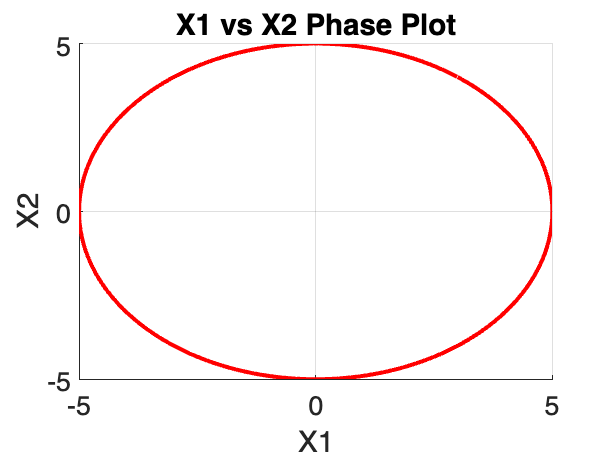

time = 0:0.01: 2*pi;

% e
grid on; hold on
set(gca,'FontSize', 20)
plot(x1(time), x2(time), 'r', "LineWidth", 3)
xlabel("X1")
ylabel("X2")
title("X1 vs X2 Phase Plot")

## Part B: Falling Apple, Nonhomogeneous Equation (No friction)

clc, clear, close all
syms s h v0 g t;
A = [0,1;0,0]; x0 = [h;v0];
% a
R = inv(s*eye(2)-A)

$$R = \left(\begin{array}{cc} \frac{1}{s} & \frac{1}{s^{2}}\\ 0 & \frac{1}{s} \end{array}\right)$$

% b
T = ilaplace(R)

$$T = \left(\begin{array}{cc} 1 & t\\ 0 & 1 \end{array}\right)$$

% c
f = sym([0;-g]);
F=laplace(f,t,s)

$$F = \left(\begin{array}{c} 0\\ -\frac{g}{s} \end{array}\right)$$

% d
xzi = T*x0

$$xzi = \left(\begin{array}{c} h+t\,v_{0}\\ v_{0} \end{array}\right)$$

% e
xzs = ilaplace(R*F)

$$xzs = \left(\begin{array}{c} -\frac{g\,t^{2}}{2}\\ -g\,t \end{array}\right)$$

% f
x = xzi + xzs

$$x = \left(\begin{array}{c} -\frac{g\,t^{2}}{2}+v_{0}\,t+h\\ v_{0}-g\,t \end{array}\right)$$

## Part C: Two Tanks – Laplace Matrix Method

clc, clear, close all
syms s t k;
A = (1/12)*[-4,1;4,-4]; 
q0=[2;4]; 
b = [6*k;0];
B = laplace(b, t, s)

$$B = \left(\begin{array}{c} \frac{6\,k}{s}\\ 0 \end{array}\right)$$


% a
R = inv(s*eye(2)-A)

$$R = \left(\begin{array}{cc} \frac{4\,\left(3\,s+1\right)}{12\,s^{2}+8\,s+1} & \frac{1}{12\,s^{2}+8\,s+1}\\ \frac{4}{12\,s^{2}+8\,s+1} & \frac{4\,\left(3\,s+1\right)}{12\,s^{2}+8\,s+1} \end{array}\right)$$


% b
T = ilaplace(R)

$$T = \left(\begin{array}{cc} \frac{{\mathrm{e}}^{-\frac{t}{2}}}{2}+\frac{{\mathrm{e}}^{-\frac{t}{6}}}{2} & \frac{{\mathrm{e}}^{-\frac{t}{6}}}{4}-\frac{{\mathrm{e}}^{-\frac{t}{2}}}{4}\\ {\mathrm{e}}^{-\frac{t}{6}}-{\mathrm{e}}^{-\frac{t}{2}} & \frac{{\mathrm{e}}^{-\frac{t}{2}}}{2}+\frac{{\mathrm{e}}^{-\frac{t}{6}}}{2} \end{array}\right)$$


% c
qzi = T*q0

$$qzi = \left(\begin{array}{c} 2\,{\mathrm{e}}^{-\frac{t}{6}}\\ 4\,{\mathrm{e}}^{-\frac{t}{6}} \end{array}\right)$$


% d
qzs = ilaplace(R*B)

$$qzs = \left(\begin{array}{c} 24\,k-6\,k\,{\mathrm{e}}^{-\frac{t}{2}}-18\,k\,{\mathrm{e}}^{-\frac{t}{6}}\\ 24\,k+12\,k\,{\mathrm{e}}^{-\frac{t}{2}}-36\,k\,{\mathrm{e}}^{-\frac{t}{6}} \end{array}\right)$$


% e
x = qzi + qzs

$$x = \left(\begin{array}{c} 24\,k+2\,{\mathrm{e}}^{-\frac{t}{6}}-6\,k\,{\mathrm{e}}^{-\frac{t}{2}}-18\,k\,{\mathrm{e}}^{-\frac{t}{6}}\\ 24\,k+4\,{\mathrm{e}}^{-\frac{t}{6}}+12\,k\,{\mathrm{e}}^{-\frac{t}{2}}-36\,k\,{\mathrm{e}}^{-\frac{t}{6}} \end{array}\right)$$

## Part D: The Rose of Venus

clc, clear, close all
syms s t c wv we;
%we=2*pi; wv=2*pi*(18/3);
Re=1; Rv=0.72;
A = [0, -2*pi;2*pi, 0]; x0=[-0.28;0.00];
%c=(wv-we)*Rv;
f=c*[-sin(wv*t);cos(wv*t)];
xe=[cos(we*t);sin(we*t)];
xv=[cos(wv*t);sin(wv*t)];
z=xv-xe;
% a
R=inv(s*eye(2)-A)

$$R = \left(\begin{array}{cc} \frac{s}{s^{2}+4\,\pi^{2}} & -\frac{2\,\pi }{s^{2}+4\,\pi^{2}}\\ \frac{2\,\pi }{s^{2}+4\,\pi^{2}} & \frac{s}{s^{2}+4\,\pi^{2}} \end{array}\right)$$

% b
F = laplace(f,t,s)

$$F = \left(\begin{array}{c} -\frac{c\,\mathrm{wv}}{s^{2}+{\mathrm{wv}}^{2}}\\ \frac{c\,s}{s^{2}+{\mathrm{wv}}^{2}} \end{array}\right)$$

% c
xzi=R*x0

$$xzi = \left(\begin{array}{c} -\frac{7\,s}{25\,\left(s^{2}+4\,\pi^{2}\right)}\\ -\frac{14\,\pi }{25\,\left(s^{2}+4\,\pi^{2}\right)} \end{array}\right)$$

% d
xzs=R*F

$$xzs = \begin{array}{l} \left(\begin{array}{c} -\frac{2\,\pi \,c\,s}{\sigma_{1}}-\frac{c\,s\,\mathrm{wv}}{\sigma_{1}}\\ \frac{c\,s^{2}}{\sigma_{1}}-\frac{2\,\pi \,c\,\mathrm{wv}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\left(s^{2}+{\mathrm{wv}}^{2}\right)\,\left(s^{2}+4\,\pi^{2}\right) \end{array}$$

% e
x = matlabFunction(simplify(ilaplace(xzi+xzs)))

x = function_handle with value:
    @(c,t,wv)[(c.*cos(t.*wv))./(wv-pi.*2.0)-(cos(t.*pi.*2.0).*(c.*2.5e+1+wv.*7.0-pi.*1.4e+1))./(wv.*2.5e+1-pi.*5.0e+1);(c.*sin(t.*wv))./(wv-pi.*2.0)-(sin(t.*pi.*2.0).*(c.*pi.*5.0e+1+wv.*pi.*1.4e+1-pi.^2.*2.8e+1))./(pi.*(wv.*2.5e+1-pi.*5.0e+1).*2.0)]


x(2.8274,4,2*pi*(18/3))

ans =    -0.2800
   -0.0000
